%Ejemplo  10 -7: Ingeniería de Control moderna Pagina 762
% Ejemplo 10-7 
% Controlador observador de orden completo
%x(0)=[1;0];
%e(0)=[0.5;0];

# Diseño de un controlador-observador de orden completo

clear
close all
% Obtener la respuesta del sistema a la condicion inicial x0 y e0
x0=[1;0];
e0=[0.5;0];
A= [0 1; 20.6 0]

A =          0    1.0000
   20.6000         0


B = [0;1]

B =      0
     1


C = [1 0]

C =      1     0


J=[-1.8+2.4*1i -1.8-2.4*1i]   % Polos deseados en lazo cerrado

J =   -1.8000 + 2.4000i  -1.8000 - 2.4000i


K=acker(A,B,J)

K =    29.6000    3.6000


L=[-8 -8] % Polos deseados del obervador

L =     -8    -8


Ke=acker(A',C',L)'

Ke =    16.0000
   84.6000


AA=[A-B*K  B*K; zeros(2,2) A-Ke*C] % ecuacion 10-70

AA =          0    1.0000         0         0
   -9.0000   -3.6000   29.6000    3.6000
         0         0  -16.0000    1.0000
         0         0  -64.0000         0


BB=eye(4)

BB =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CC=eye(4);
DD=eye(4);
sys = ss(AA,BB,CC,DD)

sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    -9  -3.6  29.6   3.6
   x3     0     0   -16     1
   x4     0     0   -64     0
 
  B = 
       u1  u2  u3  u4
   x1   1   0   0   0
   x2   0   1   0   0
   x3   0   0   1   0
   x4   0   0   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
Continuous-time state-space model.


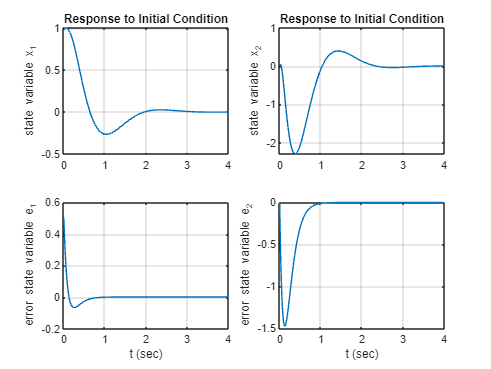

t = 0:0.01:4;
z = initial(sys,[x0;e0],t);
x1 = [1 0 0 0]*z';
x2 = [0 1 0 0]*z';
e1 = [0 0 1 0]*z';
e2 = [0 0 0 1]*z';
subplot(2,2,1)
plot(t,x1 ),grid
title('Response to Initial Condition')
ylabel('state variable x_1')
subplot(2,2,2)
plot(t,x2),grid
title('Response to Initial Condition')
ylabel('state variable x_2')
subplot(2,2,3); plot(t,e1),grid
xlabel('t (sec)'), ylabel('error state variable e_1')
subplot(2,2,4); plot(t,e2),grid
xlabel('t (sec)'), ylabel('error state variable e_2')

% O bien en forma simbolica
syms s
sImA=s*eye(size(A,1))-A

$$sImA = \left(\begin{array}{cc} s & -1\\ -\frac{103}{5} & s \end{array}\right)$$

EC=det(sImA+B*K)*det(sImA+Ke*C) % EC ecuación 10-70

$$EC = \left(s^{2}+\frac{18\,s}{5}+9\right)\,\left(s^{2}+16\,s+64\right)$$

% EC==s^4+3.6 s^3+9s^2+
%           16s^3+57.6s^2+144s
%                 64^2+230.4s     +576
% EC= s^4+19.6s^3+130.6s^2+374.4s+576
%[num1,den1]=ss2tf(AA,BB,CC,DD,1)
At=AA;
Bt=[B
    zeros(size(B))]

Bt =      0
     1
     0
     0


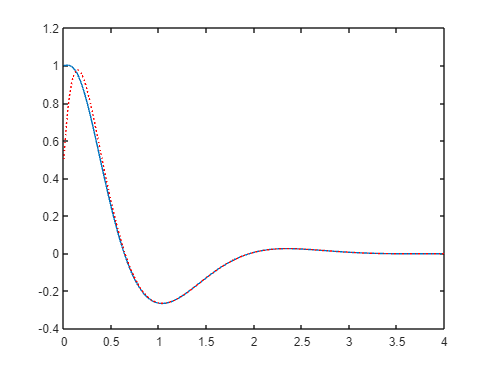

Ct = [ C    zeros(size(C)) ];
sys=ss(At,Bt,Ct,0);
[y,t,x] = lsim(sys,zeros(size(t)),t,[1 0 0.5 0]);
n = 2;
e = x(:,n+1:end);
x = x(:,1:n);
x_est = x - e;
figure(1000)
plot(t,x(:,1),t,x_est(:,1),'r:')

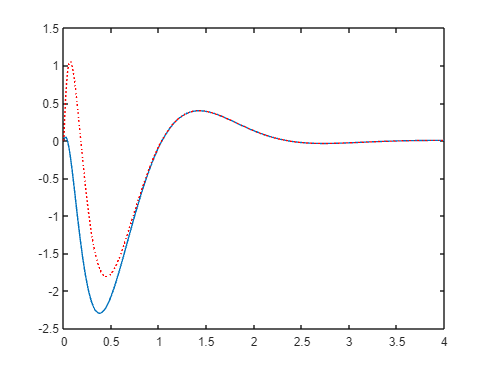

figure(2000)
plot(t,x(:,2),t,x_est(:,2),'r:')